`Load the landslide image:`

landslide_image = imread('C:\Users\abish\Downloads\Impathon\landslide_image.jpg');

`Identify the size of the landslide image:`

[height, width, ~] = size(landslide_image);
fprintf('Original size of the landslide image: %d x %d\n', height, width);

Original size of the landslide image: 969 x 1292


`Resize the image to 17x17:`

resized_image = imresize(landslide_image, [17, 17]);

`Apply poison noise to the resized image:`

noisy_image = imnoise(resized_image, 'poisson');

`Apply Gaussian filter to remove the poison noise:`

filtered_image = imgaussfilt(noisy_image, 2); %standard deviation is taken as 2

`Display the original, noisy, and filtered images:`

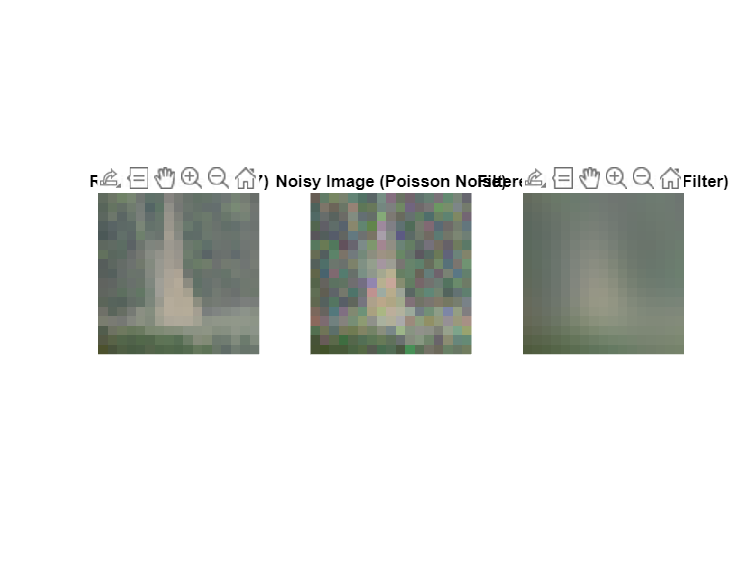

subplot(1, 3, 1);
imshow(resized_image);
title('Resized Image (17x17)');

subplot(1, 3, 2);
imshow(noisy_image);
title('Noisy Image (Poisson Noise)');

subplot(1, 3, 3);
imshow(filtered_image);
title('Filtered Image (Gaussian Filter)');